%AB-CDEFG-H
%20-42406-1
%A1=GD;A2=AF
A1=62

A1 = 62

A2=20

A2 = 20

CDE=424

CDE = 424

A1=62;
A2=20;
CDE=424;
fs=40000;
t=0:1/fs:1-1/fs;
x1=A1*cos(2*pi*(CDE*100)*t);
n=4;%4-bit channel
Levels=(2^n)-1

Levels = 15

A1=62;
A2=20;
CDE=424;
fs=40000;
t=0:1/fs:1-1/fs;
x1=A1*cos(2*pi*(CDE*100)*t);
n=4;%4-bit channel
Levels=(2^n)-1;
delta=(max(x1)-min(x1))/Levels

delta = 8.2667

A1=62;
A2=20;
CDE=424;
fs=40000;
t=0:1/fs:1-1/fs;
x1=A1*cos(2*pi*(CDE*100)*t);
n=4; %4-bit channel
x=3.2; %3.2V voltage
Levels=(2^n)-1;
delta=(max(x1)-min(x1))/Levels;
i=round((x-min(x1))/delta);
Xq=min(x1)+i.*delta

Xq = 4.1333

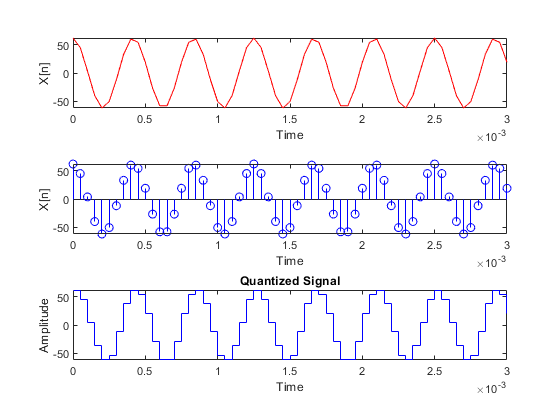

A1=62;
A2=20;
CDE=424;
fs=20000;
t=0:1/fs:0.003;
x1=A1*cos(2*pi*(CDE*100)*t);
n=4; %4-bit channel
Levels=(2^n)-1;
delta=(max(x1)-min(x1))/Levels;
i=round((x1-min(x1))/delta);
Xq=min(x1)+i.*delta;
subplot(3,1,1)
plot(t,x1,'R');
xlabel('Time')
ylabel('X[n]')
subplot(3,1,2)
stem(t,x1,'b');
xlabel('Time')
ylabel('X[n]')
subplot(3,1,3)
stairs(t,Xq,'b');
title('Quantized Signal')
xlabel('Time')
ylabel('Amplitude')